load exampleMaps.mat;
whos *Map*

  Name              Size               Bytes  Class      Attributes

  complexMap       41x52                2132  logical              
  emptyMap         26x27                 702  logical              
  simpleMap        26x27                 702  logical              
  ternaryMap      501x501            2008008  double               



rng("default");
%map = mapMaze(5,1,'MapSize',[10 20],'MapResolution',2);
map = binaryOccupancyMap(simpleMap,2);
robotRadius = 0.1;
inflate(map, robotRadius);


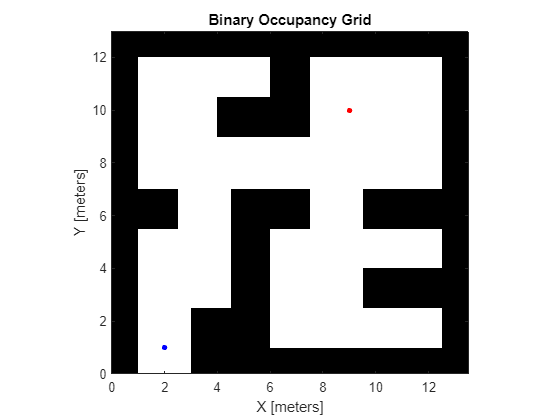

start_x = 2;
start_y = 1;
goal_x = 9;
goal_y = 10;
orinetation = 0;
robot_pose = [start_x start_y orinetation];
goal_pose = [goal_x, goal_y];
robot_vel = 0.1;
dt = 0.2;
f1 = figure;
f2 = figure;
f3 = figure;
figure(f1);
show(map);
hold on
plot(robot_pose(1), robot_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2);
plot(goal_pose(1), goal_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2, 'Color',"red");

teszt = 1;
lidar = rangeSensor;
vfh = controllerVFH;
vfh.RobotRadius = robotRadius;
vfh.DistanceLimits = [0.05 1.5];
vfh.UseLidarScan = true;
vfh.SafetyDistance = 0.4;
speed_control = 0;
trigger = true

trigger = logical
   1


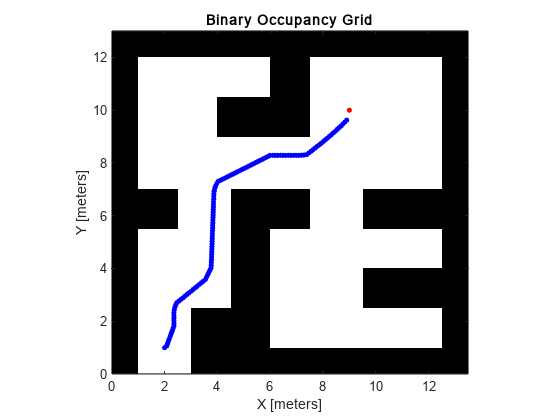

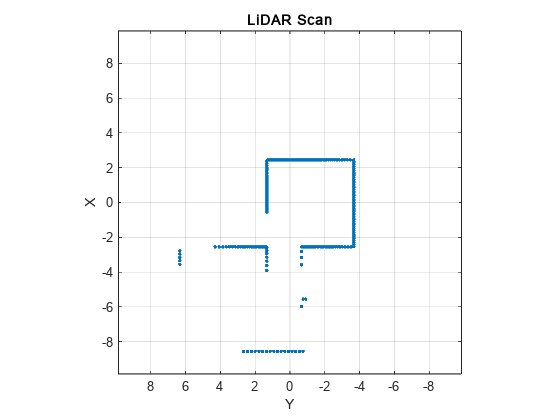

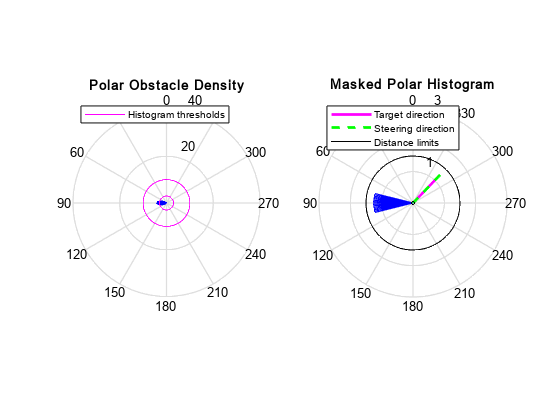

trigger = logical
   0


while trigger
    
    %if teszt >1 && min(ranges) < 0.35 && speed_control == 0
    %    robot_vel= abs(robot_vel/2);
    %    speed_control = 1;
    %elseif teszt >1 && min(ranges) > 0.35 
    %    robot_vel = 0.2;
    %    speed_control = 0;
    %end


    [ranges,angles] = lidar(robot_pose,map);


    scan = lidarScan(ranges,angles);
    transformedScan = transformScan(scan,robot_pose);
    rotateScan = transformScan(scan,[0,0,robot_pose(3)+deg2rad(270)]);
    
    %Mentsük el a teljes környezetet egy nagy map-be, amit megjegyez és
    %azzal lehet csinálni, hogy ne menjen olyan helyre ahol volt már

    figure(f3);
    plot(rotateScan)


    tavolsag_x = goal_pose(1) - robot_pose(1);
    tavolsag_y = goal_pose(2) - robot_pose(2);
    hosszanti_atlo = sqrt(tavolsag_x^2+tavolsag_y^2);
    goal_angle = 1.5*pi + sin(tavolsag_y/hosszanti_atlo);  
    %sind(tavolsag_y/hosszanti_atlo)
    %goal_angle = sin(tavolsag_y/hosszanti_atlo);
    
    steeringDir = vfh(rotateScan,goal_angle);
    new_deg = rad2deg(steeringDir)+90;
    
    robot_pose(3) = steeringDir;
    robot_pose(1) = robot_pose(1)+cosd(new_deg)*robot_vel;
    robot_pose(2) = robot_pose(2)+sind(new_deg)*robot_vel;
    robot_pose;
    figure(f1);
    plot(robot_pose(1), robot_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2)
    figure(f2);
    show(vfh)
    drawnow
    teszt = teszt +1;
    if hosszanti_atlo <= 0.5
        trigger = false
    end

end